## **Chapter 3: **Introduction to MATLAB Programming 

**Exercise 2**

% This script calculates the volume of a hollow sphere
% Assign the radii
rIn = 5.1

rIn = 5.1000

rOut = 6.8

rOut = 6.8000


% Calculate the volume
vSphere = 4/3*pi.*(rOut.^3 - rIn.^3)

vSphere = 761.4425

**Exercise 3**

favNum = input('Enter your favourite number: ')

favNum = 5

**Exercise 4**

yourName = input('Enter your name: ','s')

yourName = 'Thorsten'

**Exercise 5**

realNum = input('Enter a real number: ');
fprintf('Your number is %.2f\n',realNum)

Your number is 5.00


**Exercise 6**

n = 12345.6789

n = 1.2346e+04

fprintf('The number is %f',n)

The number is 12345.678900

fprintf('The number is %10.4f',n)

The number is 12345.6789

fprintf('The number is %10.2f',n)

The number is   12345.68

fprintf('The number is %6.4f',n)

The number is 12345.6789

fprintf('The number is %2.4f',n)

The number is 12345.6789

**Exercise 7**

n = 12345

n = 12345

fprintf('The number is %d',n)

The number is 12345

fprintf('The number is %5d',n)

The number is 12345

fprintf('The number is %8d',n)

The number is    12345

fprintf('The number is %3d',n)

The number is 12345

**Exercise 8**

% 'disp' does not allow any formatting -> quick/dirty ouput
% using 'fprintf' formatting is required -> fancy/meaningful output

**Exercise 9**

% Echostring
yourString = input('Type in your string: ','s')

yourString = 'HUGE'

fprintf('Your string goes here: %s',yourString)

Your string goes here: HUGE

**Exercise 10**

% Thirdside
b = input('Enter the first side: ')

b = 3

c = input('Enter the second side: ')

c = 4

alpha = input('Enter the angle between them [deg]: ')

alpha = 50


% a = sqrt(b.^2 + c.^2 - 2*b.*c.*cos(alpha*pi/180))
fprintf('The third side is %.3f', thirdside(b,c,alpha))

The third side is 3.094

**Exercise 11**

% Justify
c = input('Type in your character: ','s')

c = 'Q'

fprintf('Your character |%-5c|',c)

Your character |Q    |

fprintf('Your character |%3c|',c)

Your character |  Q|

**Exercise 12**

lumin

This script will calculate the luminosity of a star.
When prompted, enter the star' s distance from the sun
  in meters, and its brightness in W/meters squared.
The luminosity of this star is 29053.45 watts

**Exercise 13**

% iotrace
mynum = input('Please enter a number: ')

mynum = 7

mychar = input('Please enter a character: ','s')

mychar = 'd'


fprintf('Your number is %.2f\n',mynum)

Your number is 7.00


fprintf('Your char is %6c!\n',mychar)

Your char is      d!


**Exercise 14**

x = 7.5

x = 7.5000

y = 1.8

y = 1.8000

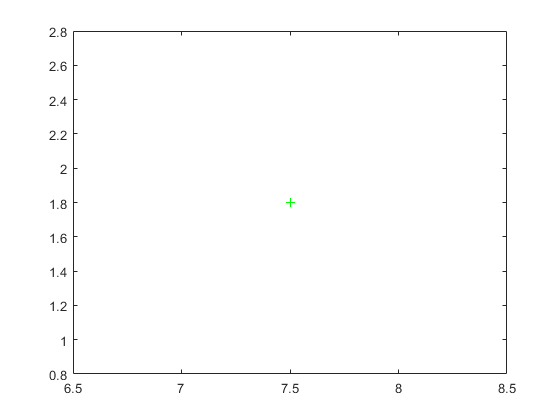

plot(x,y,'g+')

**Exercise 15**

x10 = linspace(0,pi,10)

x10 =          0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416


x100 = linspace(0,pi,100)

x100 =          0    0.0317    0.0635    0.0952    0.1269    0.1587    0.1904    0.2221    0.2539    0.2856    0.3173    0.3491    0.3808    0.4125    0.4443    0.4760    0.5077    0.5395    0.5712    0.6029    0.6347    0.6664    0.6981    0.7299    0.7616    0.7933    0.8251    0.8568    0.8885    0.9203


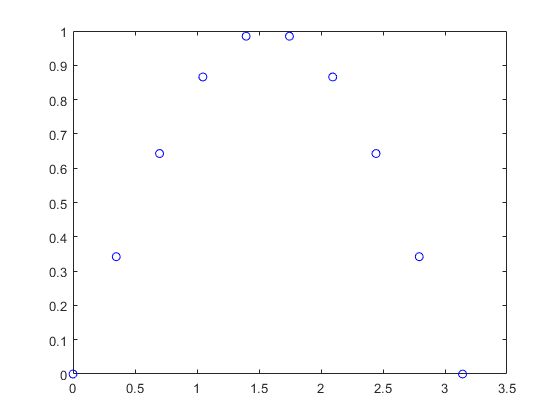


plot(x10,sin(x10),'bo')

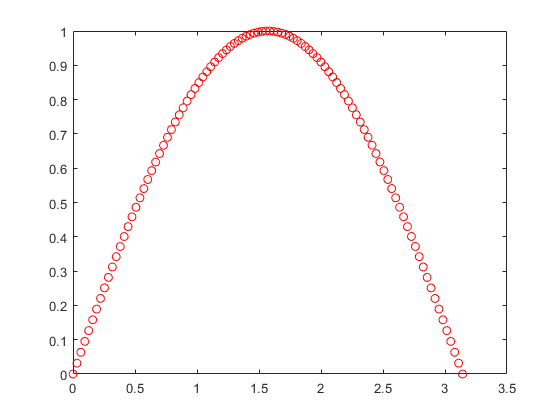

plot(x100,sin(x100),'ro')

**Exercise 16**

% If more than one graph is diaplayed in a plot

**Ecercise 17**

% 'Cuz we don't want any annoying ouput!

**Exercise 18**

altitemp = [1000 2000 3000; 288 281 269]'

altitemp =         1000         288
        2000         281
        3000         269


save 'altitemp.dat' 'altitemp' -ascii
clear

load altitemp.dat
x = altitemp(:,1)

x =         1000
        2000
        3000


y = altitemp(:,2)

y =    288
   281
   269


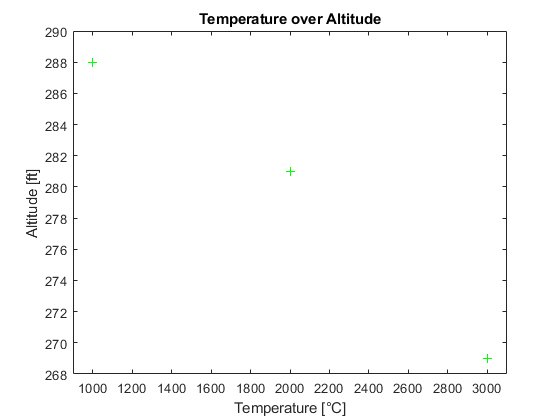

plot(x,y,'g+')
axis([900 3100 268 290])
title('Temperature over Altitude')
xlabel('Temperature [°C]')
ylabel('Altitude [ft]')

**Exercise 19**

n = randi(20)

n = 1

vec = 1:2:n

vec = 1

vecSq = vec.^2

vecSq = 1

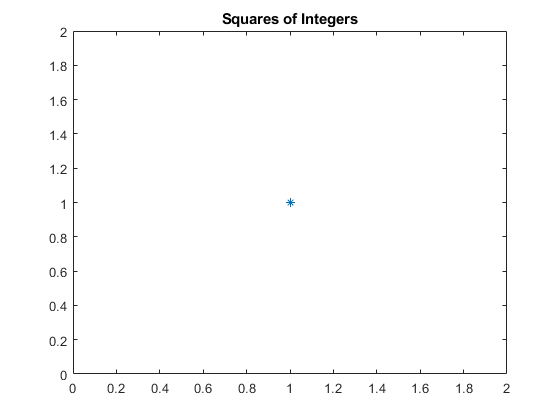

plot(vecSq,'*')
title('Squares of Integers')

**Exercise 20**

mat = randi([50 100],3,6)

mat =     95    55    84    55    89    95
    96    63    56    83    86    67
    90    67    86    75    96    85


save randfile.dat mat -ascii
newmat = randi([50 100],2,6)

newmat =     60    87    74    81    93    79
    51    75    96    81    91    59


save randfile.dat newmat -ascii -append
clear
load randfile.dat
disp(randfile)

    95    55    84    55    89    95
    96    63    56    83    86    67
    90    67    86    75    96    85
    60    87    74    81    93    79
    51    75    96    81    91    59



**Exercise 21**

dura = 120;
intv = 10;
time = 10:intv:dura;
nelm = length(time);
diam = 200 + 1.* randn(1,nelm);
partdiam = [time;diam]'

partdiam =    10.0000  199.3484
   20.0000  201.1921
   30.0000  198.3882
   40.0000  199.9755
   50.0000  198.0512
   60.0000  201.0205
   70.0000  200.8617
   80.0000  200.0012
   90.0000  199.9292
  100.0000  197.5137


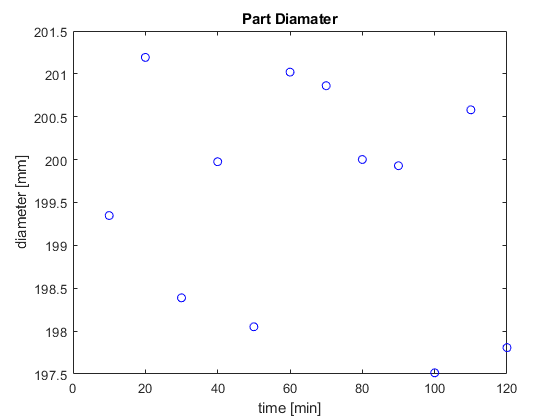

save partdiam.dat partdiam -ascii;

clear;
load partdiam.dat;
time = partdiam(:,1);
diam = partdiam(:,2);

plot(time,diam,'bo')
title('Part Diamater')
xlabel('time [min]')
ylabel('diameter [mm]')

**Exercise 22**

mat = -1 + 4.*rand(2,3)

mat =    -0.7142   -0.6131    2.2702
    1.0866    2.2726    1.8898


save testtan.dat mat -ascii

clear
load testtan.dat

tanmat = tan(testtan)

tanmat =    -0.8669   -0.7035   -1.1887
    1.9013   -1.1829   -3.0281


**Exercise 23**

l = 2.25

l = 2.2500

b = 4.00

b = 4


fprintf('The area of a rectange with\n')

The area of a rectange with


fprintf('    length = %.2f mm\n', l)

    length = 2.25 mm


fprintf('    width  = %.2f mm\n', b)

    width  = 4.00 mm


fprintf('is %.2f mm^2',calcrectarea2(l,b))

is 9.00 mm^2

**Exercise 24**

mwh = 17.23

mwh = 17.2300

fprintf('%.2f MWh equals %.2f GJ',mwh,mwh_to_gj(mwh))

17.23 MWh equals 62.03 GJ

**Exercise 26**

lmd = 4711.3

lmd = 4.7113e+03

fprintf('The angular wavlength of lambda = %.2f equals to %.2f',lmd,makeitangular(lmd))

The angular wavlength of lambda = 4711.30 equals to 749.83

**Exercise 27**

r = input('Enter your number of rows: ')

r = 2

c = input('Enter your number of cols: ')

c = 3

disp(fives(r,c))

     5     5     5
     5     5     5



**Exercise 28**

testval = randi([0 1000000],10,1)

testval =       149865
      659605
      518595
      972975
      648992
      800331
      453798
      432391
      825314
       83469


divby4 = isdivby4(testval)

divby4 = 10×1 logical array
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0


[test divby4]

Undefined function or variable 'test'.

values = resmat(testval & divby4)

**Exercise 30**

a = 3;
b = 4;
c = 5;
fprintf('%d, %d and %d form a pythagorean triple: %d',a,b,c,ispythag(a,b,c))

**Exercise 31**

vecout(4)

**Exercise 32**

pickone(5:15)

**Exercise 33**

rain = input('Enter the amount of rain [inch]: ')
fprintf('The equivalent height of snow to %.1f inch of rain is %.1f inch\n',rain,snowequiv(rain))

**Exercise 34**

tcold = input('Enter cold reservoir temperature [°C]: ')
thot = input('Enter hot reservoir temperature [°C]: ')
disp('The maximum possible efficiency of a heat engine operating between')
fprintf('%.1f °C and %.2f °C is %.2f %%\n',tcold,thot,carneff(tcold,thot).*100)

**Exercise 35**

ns = 100
t1 = 0
t2 = 5
x = linspace(t1,t2,ns)
tau1 = input('Enter first tau: ')
tau2 = input('Enter second tau: ')
A = 1 
y1 = expfct(A,tau1,x)
y2 = expfct(A,tau2,x)

hold on
plot(x,y1,'r')
plot(x,y2,'b')
legend('tau=0.3','tau=1.3')

a1 = 23

a2 = 45

The velocity v2 will decrease


vec =      5     0    11     2


ans = -99

result = 16.2500

ans =     4.5000    9.3333   16.2500   25.2000


ph = 7.8000

A pH-value of 7.8 is BASIC

ans = 3.1416

ans =      1     2     3     4
     5     6     7     8


ans =      1     2     3     4     5     6     7     8     9    10


ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


ERROR!

ERROR!!!

199 is an odd number

windspd = 74

A storm of a windspeed of 74 is a TROPICAL STORM

ranforce = 7

This is a gale
